# MSD.mlx

% =============================================================

%  Copyright © 2023-2025 Xiaofeng Dai (xiaofend@umich.edu)

%  SPDX-License-Identifier: GPL-3.0-or-later

%

%  This program is free software: you can redistribute it and/or modify

%  it under the terms of the GNU General Public License as published by

%  the Free Software Foundation, either version 3 of the License, or

%  (at your option) any later version.

%

%  This program is distributed in the hope that it will be useful,

%  but WITHOUT ANY WARRANTY; without even the implied warranty of

%  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the

%  GNU General Public License for more details.

%

%  You should have received a copy of the GNU General Public License

%  along with this program (LICENSE file in the repository root).

%  If not, see <https://www.gnu.org/licenses/>.

%

%  Tested with: MATLAB R2024a and R2022a

% =============================================================

### Select folder

Folder = uigetdir('Example_Folder/subfolder');
load(strcat(Folder,filesep,'Results_Filter',filesep,'Traj_bytrack.mat'))

## Reffer to this website: 

### [http://tinevez.github.io/msdanalyzer/](http://tinevez.github.io/msdanalyzer/)

Find the code here: [https://www.mathworks.com/matlabcentral/fileexchange/40692-mean-square-displacement-analysis-of-particles-trajectories](https://www.mathworks.com/matlabcentral/fileexchange/40692-mean-square-displacement-analysis-of-particles-trajectories)

### Set up parameters and calculate MSD for each traj

% create msdanalyzer class and load trajectory
ma = msdanalyzer(2, 'µm', 's');
ma = ma.addAll(Traj_bytrack);
disp(ma)

  msdanalyzer with properties:

      TOLERANCE: 12
         tracks: {98×1 cell}
          n_dim: 2
    space_units: 'µm'
     time_units: 's'
            msd: []
          vcorr: []
           lfit: []
      loglogfit: []
          drift: []



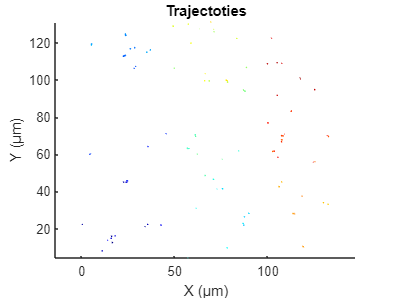


% Visolize trajectories
figure
ma.plotTracks;
ma.labelPlotTracks;
title Trajectoties


disp('------------------------------------------------------')

------------------------------------------------------



% Calculate MSD for each trajectory
ma = ma.computeMSD;

Computing MSD of 98 tracks...   Done.


MSD_bytrack=ma.msd;

### plot MSD curve (by each trajectory)

figure
ma.plotMSD;
title '\fontsize{14}MSD curve of each Trajectory'
mkdir([Folder,filesep,'Results_MSD'])

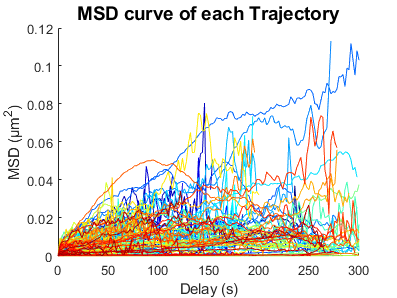

saveas(gcf,[Folder,filesep,'Results_MSD',filesep,'MSD_SinglePlot.png'])

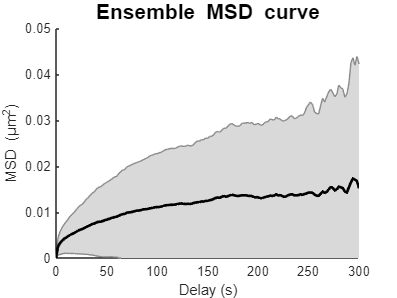

saveas(gcf,[Folder,filesep,'Results_MSD',filesep,'MSD_SinglePlot.fig'])

figure
ma.plotMeanMSD(gca, true)
title '\fontsize{14}Ensemble MSD curve'

% shadow --> weighted standard deviation over all MSD curves

disp('------------------------------------------------------')

------------------------------------------------------


### plot MSD curve (ensemble)

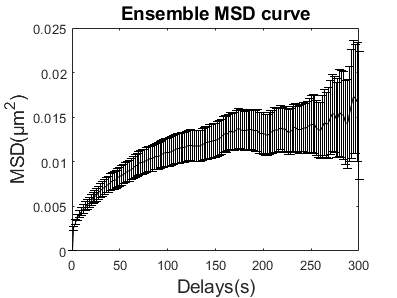

% mmsd data structure [ dT M STD N ]
figure
mmsd = ma.getMeanMSD;
t = mmsd(:,1);
x = mmsd(:,2);
dx = mmsd(:,3) ./ sqrt(mmsd(:,4));
errorbar(t, x, dx, 'k')
% error bar --> standard error of the mean
title '\fontsize{14}Ensemble MSD curve'
ylabel ('MSD(µm^2)','FontSize',14);
xlabel ('Delays(s)','FontSize',14);
saveas(gcf,[Folder,filesep,'Results_MSD',filesep,'MSD_EnsemblePlot.png'])

saveas(gcf,[Folder,filesep,'Results_MSD',filesep,'MSD_EnsemblePlot.fig'])

disp('------------------------------------------------------')

------------------------------------------------------


### plot histogram of exponent and diffusion coefficient of each trajectory

ma = ma.fitLogLogMSD(0.3); % 0.3 --> portion taken from the curves.

Fitting 98 curves of log(MSD) = f(log(t)), taking only the first 30% of each curve... Done.


ma.loglogfit

ans = struct with fields:
        alpha: [98×1 double]
        gamma: [98×1 double]
        r2fit: [98×1 double]
    alpha_lci: [98×1 double]
    alpha_uci: [98×1 double]


r2fits = ma.loglogfit.r2fit;
alphas = ma.loglogfit.alpha;

R2LIMIT = 0.7;

% Remove bad fits
bad_fits = r2fits < R2LIMIT;
fprintf('Keeping %d fits (R2 > %.2f).\n', sum(~bad_fits), R2LIMIT);

Keeping 58 fits (R2 > 0.70).


alphas(bad_fits) = [];

% Remove super diffusion
sup_diff = alphas>1;
fprintf('Keeping %d fits (α > %.2f).\n', sum(~sup_diff), 1);

Keeping 58 fits (α > 1.00).


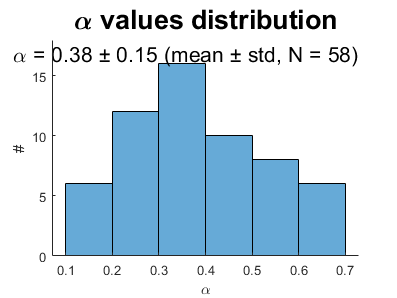

alphas(alphas>1) = [];


% Prepare string
str = { [ '\alpha = ' sprintf('%.2f ± %.2f (mean ± std, N = %d)', mean(alphas), std(alphas), numel(alphas)) ] };

figure
histogram(alphas);
box off
xlabel('\alpha')
ylabel('#')

yl = ylim(gca);
xl = xlim(gca);
text(xl(2), yl(2)+2, str, ...
    'HorizontalAlignment', 'right', ...
    'VerticalAlignment', 'top', ...
    'FontSize', 16)
title('\alpha values distribution', ...
    'FontSize', 20)
ylim([0 yl(2)+2])
saveas(gcf,[Folder,filesep,'Results_MSD',filesep,'Exponent_Dis.png'])

saveas(gcf,[Folder,filesep,'Results_MSD',filesep,'Exponent_Dis.fig'])

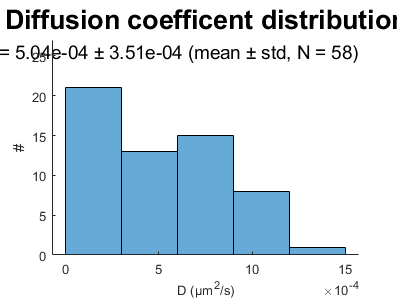

gammas = ma.loglogfit.gamma;
gammas(bad_fits) = []; % discard bad fits, like for alpha
gammas(sup_diff) = []; % discard super diffusions

Dmean = mean( gammas ) / 2 / ma.n_dim;
Dstd  =  std( gammas ) / 2 / ma.n_dim;

figure
histogram(gammas/ 2 / ma.n_dim);
box off
xlabel('D')
ylabel('#')


str2 = { [ 'D = ' sprintf('%.2e ± %.2e (mean ± std, N = %d)',Dmean, Dstd, numel(gammas)) ] };


yl = ylim(gca);
xl = xlim(gca);
text(xl(2), yl(2)+2, str2, ...
    'HorizontalAlignment', 'right', ...
    'VerticalAlignment', 'top', ...
    'FontSize', 14)
title('Diffusion coefficent distribution', ...
    'FontSize', 20)
ylim([0 yl(2)+2])
xlabel ('D (µm^2/s)','FontSize',10);
saveas(gcf,[Folder,filesep,'Results_MSD',filesep,'Diffusion_Dis.png'])

saveas(gcf,[Folder,filesep,'Results_MSD',filesep,'Diffusion_Dis.fig'])

disp('------------------------------------------------------')

------------------------------------------------------


clear xl yl bad_fits sup_diff str str2 htest a0 a1 pval


### Save exponent and disffusion coefficient of each traj

Dis_exp=alphas;
Dis_diffusion=gammas/(2*ma.n_dim);
save([Folder,filesep,'Results_MSD',filesep,'Dist_exp.mat'],'Dis_exp')
save([Folder,filesep,'Results_MSD',filesep,'Dist_diffusion.mat'],'Dis_diffusion')